# Behavioral data analysis

Multilevel GLM to examine the effects of temperature and regulation (and their interactions) on pain ratings (to run this, you need to install CanlabCore https://github.com/canlab/CanlabCore)

clear;
close all;
load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');

for i = 1:numel(D.Event_Level.data)
    y_int{i} = D.Event_Level.data{i}(:,12);         % intensity ratings: 0 to 100
    y_unp{i} = -2*(D.Event_Level.data{i}(:,13)-50); % unpleasant ratings: -100 to 100
    xx{i} = [D.Event_Level.data{i}(:,11) D.Event_Level.data{i}(:,16) ...
        scale(D.Event_Level.data{i}(:,11),1).*scale(D.Event_Level.data{i}(:,16),1)];
                                                    % xx: independent variable 
                                                    % temperature, regulation, and 
                                                    % interaction between temperature and regulation
    reg{i} = D.Event_Level.data{i}(:,16);
    temp{i} = D.Event_Level.data{i}(:,11);
end


## 1. GLM results for up vs. down

1-1. intensity

% multilevel GLM analysis for intensity ratings with bootstrap tests (10000 iterations)
stats{1} = glmfit_multilevel(y_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.00 s, bias correct in 0.00 s 
Total time: 0.46 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-215.18	5.01	2.12	0.54	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-215.33	5.01	2.12	0.54	
STE	13.79	0.31	0.35	0.12	
t	-15.46	15.82	5.94	4.26	
Z	-3.53	3.92	3.94	3.78	
p	0.0004	0.0001	0.0001	0.0002	

________________________________________


1-2. unpleasantness

% multilevel GLM analysis for unpleasantness ratings with bootstrap tests (10000 iterations)
stats{2} = glmfit_multilevel(y_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000); 


Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.62 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-245.01	5.50	5.20	0.30	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-245.00	5.50	5.19	0.30	
STE	16.89	0.38	0.68	0.20	
t	-14.23	14.32	7.57	1.50	
Z	-3.55	3.49	4.44	1.45	
p	0.0002	0.0002	0.0000	0.0732	

________________________________________


## 2. GLM results for up vs. passive

% up vs. passive
for i = 1:numel(xx)
    idx = xx{i}(:,2)==1 | xx{i}(:,2)==0;
    y_int2{i} = y_int{i}(idx);
    y_unp2{i} = y_unp{i}(idx);
    xx2{i} = xx{i}(idx,:);
    xx2{i} = [xx2{i}(:,1) scale(xx2{i}(:,2),1) scale(xx2{i}(:,1),1).*scale(xx2{i}(:,2),1)];
end


2-1. intensity

stats2{1} = glmfit_multilevel(y_int2, xx2, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.74 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-232.27	5.40	1.44	-0.17	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-232.18	5.40	1.44	-0.17	
STE	15.03	0.34	0.52	0.21	
t	-15.24	15.65	2.71	-0.81	
Z	-3.38	3.71	2.46	-0.20	
p	0.0004	0.0001	0.0069	0.4199	

________________________________________


2-2. unpleasantness

stats2{2} = glmfit_multilevel(y_unp2, xx2, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
   'verbose', 'boot', 'nresample', 10000); 


Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.60 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-255.43	5.78	4.79	-0.47	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-255.41	5.78	4.77	-0.47	
STE	17.36	0.39	0.77	0.37	
t	-14.35	14.52	6.04	-1.24	
Z	-3.31	3.76	3.80	-1.07	
p	0.0005	0.0001	0.0001	0.1433	

________________________________________


% passive vs. down

for i = 1:numel(xx)
    idx = xx{i}(:,2)==-1 | xx{i}(:,2)==0;
    y_int3{i} = y_int{i}(idx);
    y_unp3{i} = y_unp{i}(idx);
    xx3{i} = xx{i}(idx,:);
    xx3{i} = [xx3{i}(:,1) scale(xx3{i}(:,2),1) scale(xx3{i}(:,1),1).*scale(xx3{i}(:,2),1)];
end


## 3. GLM results for passive vs. down

3-1. intensity

stats3{1} = glmfit_multilevel(y_int3, xx3, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000);

1. intensity ========================


Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.02 s, bias correct in 0.00 s 
Total time: 0.68 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-209.20	4.86	2.80	1.25	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-209.29	4.86	2.80	1.25	
STE	13.97	0.32	0.56	0.25	
t	-14.65	14.99	5.04	4.96	
Z	-3.44	3.64	4.02	3.84	
p	0.0003	0.0001	0.0000	0.0001	

________________________________________


3-2. unpleasantness

stats3{2} = glmfit_multilevel(y_unp3, xx3, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
     'verbose', 'boot', 'nresample', 10000); 


Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: unweighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 0.68 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-247.04	5.49	5.63	1.08	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-246.43	5.47	5.62	1.08	
STE	19.78	0.44	1.02	0.36	
t	-12.26	12.33	5.41	2.98	
Z	-3.86	3.21	5.50	3.34	
p	0.0001	0.0007	0.0000	0.0004	

________________________________________


## 4. Plotting the effects of temperature and regulation on pain ratings (intensity and unpleasantness)

4-1. Plot for intensity ratings (Figure 2 in the manuscript)

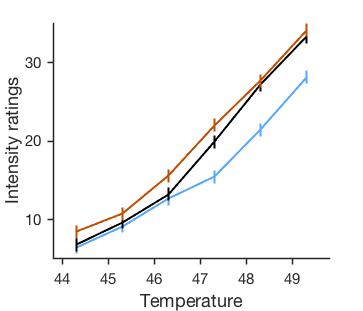

clear dat*; 

dosavefig = false; % save figure in matlab 2014 (was written in 2014 previously)
figdir = '../figures';

u_temp = unique(temp{1});
u_reg = unique(reg{1});

for subj = 1:numel(temp)
    for i = 1:numel(u_temp)
        for j = 1:numel(u_reg)
            dat_int{subj}(i,j) = nanmean(y_int{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
            dat_unp{subj}(i,j) = nanmean(y_unp{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
        end
    end
end

for subj = 1:numel(temp)
    reg_all{1}(:,subj) = dat_int{subj}(:,1);
    reg_all{2}(:,subj) = dat_int{subj}(:,2);
    reg_all{3}(:,subj) = dat_int{subj}(:,3);
end

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);

create_figure('plot');
if dosavefig
    set(gcf, 'Position', [1   512   268   194]);
else
    set(gcf, 'Position', [1   394   363   311]);
end

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end

set(gca, 'xlim', [43.8 49.8], 'linewidth', 1.5, 'xtick', 44:49, 'tickdir',...
    'out', 'ticklength', [.02 .02], 'ytick', 0:10:50);
if dosavefig
    set(gca, 'fontsize', 20);
    
    %figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
    savename = fullfile(figdir, 'behavioral_int_full.pdf');
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xlabel('Temperature', 'fontsize', 18);
    ylabel('Intensity ratings', 'fontsize', 18);
end

4-2. Plot for unpleasantness ratings (Figure 2 in the manuscript)

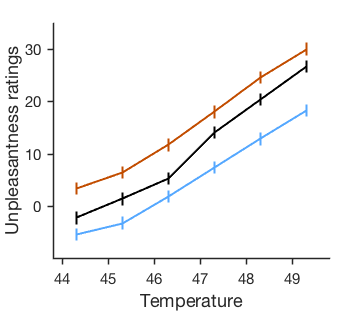

for subj = 1:numel(temp)
    reg_all{1}(:,subj) = dat_unp{subj}(:,1);
    reg_all{2}(:,subj) = dat_unp{subj}(:,2);
    reg_all{3}(:,subj) = dat_unp{subj}(:,3);
end

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);

create_figure('plot');
if dosavefig
    set(gcf, 'Position', [1   512   268   194]);
else
    set(gcf, 'Position', [1   394   363   311]);
end

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end
set(gca, 'xlim', [43.8 49.8], 'ylim', [-10 35], 'linewidth', 1.5, 'xtick', 44:49, 'ytick', 0:10:30, 'tickdir', 'out', 'ticklength', [.02 .02]);
if dosavefig
    set(gca, 'fontsize', 20);
    
    %figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
    savename = fullfile(figdir, 'behavioral_unp_full.pdf');
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xlabel('Temperature', 'fontsize', 18);
    ylabel('Unpleasantness ratings', 'fontsize', 18);
end

## 5. Plotting glm results 

5-1. pain intensity

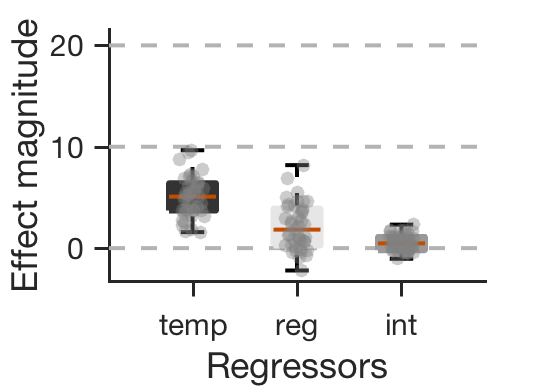


dosavefig = false;
edgecolor = 'k';
facecolor = [.2 .2 .2;
    .9 .9 .9;
    .6 .6 .6];

close all;
boxplot_wani_2016(stats{1}.first_level.beta(2:4,:)', 'color', facecolor, 'refline', [0 10 20], 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position',  [1   512   268   194]);
set(gca, 'fontsize', 20, 'linewidth', 1.5, 'ticklength', [.04 .04]);

h = scatter(reshape(repmat(1:3, 41, 1), 41*3,1)+scale(rand(41*3,1))/15, ...
    reshape(stats{1}.first_level.beta(2:4,:)', 41*3,1), 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);
set(gca, 'ylim', [-3.2380 21.6158]);

if dosavefig
    savename = fullfile(figdir, 'int_glm_box.pdf');
    
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xticklabels({'temp', 'reg', 'int'});
    ylabel('Effect magnitude', 'fontsize', 18);
    xlabel('Regressors', 'fontsize', 18);
end

5-2. unpleasantness

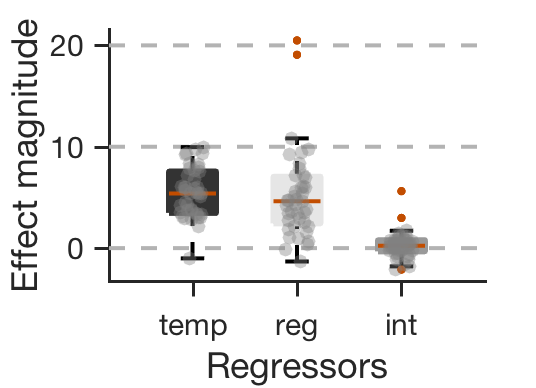


close all;
boxplot_wani_2016(stats{2}.first_level.beta(2:4,:)', 'color', facecolor, 'refline', [0 10 20], 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position',  [1   512   268   194]);
set(gca, 'fontsize', 20, 'linewidth', 1.5, 'ticklength', [.04 .04]); %, 'ylim', [-2.7997   12.2488]);

% Outliers are marked already
outlier_index = [59    64    92   100];
random_x = scale(rand(41*3,1))/15;

x = reshape(repmat(1:3, 41, 1), 41*3,1)+random_x;
x(outlier_index) = [];

y = reshape(stats{2}.first_level.beta(2:4,:)', 41*3,1);
y(outlier_index) = [];

h = scatter(x, y, 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);
% set(gca, 'ylim', [-2.7997 10.5]);

if dosavefig
    savename = fullfile(figdir, 'unp_glm_box.pdf');
    
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xticklabels({'temp', 'reg', 'int'});
    ylabel('Effect magnitude', 'fontsize', 18);
    xlabel('Regressors', 'fontsize', 18);
end